m = 0.312;
M = 0.400;
Mw = 0.05;
I = 0.00024;
l = 0.02;
g = 9.81;
r = 0.0335;
d = 0.165;
Iw = 0.00002805*3;
Ip = 0.00001972;
R = 10;
k_T = 0.11;
t1 = ((m+2*Mw+M)*m*l*g)/(((m+2*Mw+M)*I + (M+m+2*Mw)*m*l*l));

t2 = -(m*m*g*l*l)/((M+2*Mw)*I + (M+2*Mw)*m*l*l);

t3 = -(m*l)/((M+2*Mw+m)*I + (M+2*Mw)*m*l*l);

t4 = (I + m*l*l)/(((M+2*Mw+m)*I + ((M+2*Mw)*m*l*l))*r) ;
t5 = (2*d)/(r*(2*Iw+Ip));

% A = [0 1 0 0 0; t1 0 0 0 0; t2 0 0 0 0; 0 0 0 0 1; 0 0 0 0 0];
% B = (k_T/R)*[0 0; t3 0; t4 0; 0 0;0 t5]*[1 1; 1 -1];
A = [0 1 0 0 0 0; t1 0 0 0 0 0;0 0 0 1 0 0; t2 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 0 0 0];
B = (k_T/R)*[0 0; t3 0;0 0; t4 0; 0 0;0 t5]*[1 1; 1 -1];
n = 6;% no of states
m = 2; % no of controls
C = eye(n);
D = zeros([n,m]);
Ts = 0.005;
% ds = ss(A,B,C,D,Ts);
Plant = ss(A,B,C,D,Ts);
Planttf = tf(Plant);

Ad = Plant.A;
Bd = Plant.B;

## Discrete plant LQR

Q = diag([100,1,1,10,1,1]); % alpha, alphadot, integral of vel, velocity,theta , thetadot
RR = diag([0.1,0.1]);

K = dlqr(Ad,Bd,Q,RR)

K =  -314.4720   -0.0000   -0.0000    0.0000    0.0000   -0.0000
 -314.4720   -0.0000   -0.0000    0.0000    0.0000   -0.0000


Ac = (Ad-Bd*K); % in CL only A changes the other remains the same
poles = eig(Ac)

poles =   -0.0775 + 0.0000i
   0.0775 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


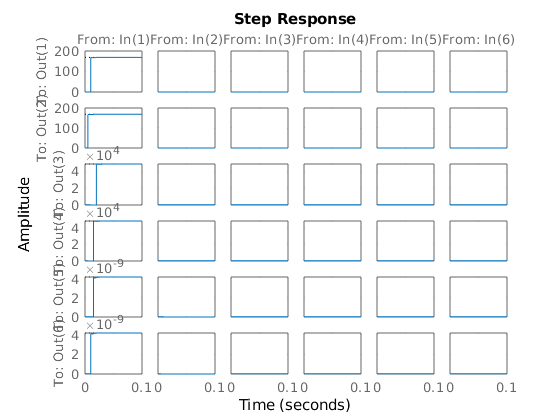

CL = feedback(Plant*K,eye(n));
step(CL)

X = [1;0;0;3;2;0];
Xd = [0;0;0;0;1;0];
for i = 1:100    
    X = (Ad-Bd*K)*X + Bd*K*Xd;
    u = -K*X;
    disp(X(1));
end

     0

    0.0060

  -3.8652e-13

   3.6009e-05

  -5.8921e-15

   2.1608e-07

  -1.3317e-15

   1.2967e-09

  -1.2907e-15

   7.7797e-12

  -1.2904e-15

   4.5402e-14

  -1.2904e-15

  -1.0102e-15

  -1.2904e-15

  -1.2887e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.2904e-15

  -1.

## LQR for 2 systems

Q1 = diag([100000,1]);%,1,10]);
Q2 = diag([1,1]); % alpha, alphadot, integral of vel, velocity,theta , thetadot
RR = diag([0.1,0.1]);

A1 = A(1:4,1:4);
B1 = B(1:4,:);
A2 = A(5:6,5:6);
B2 = B(5:6,:);
A1 = A(1:2,1:2);
B1 = B(1:2,:);

n1 = 2;% no of states
m1 = 2; % no of controls
C1 = eye(n1);
D1 = zeros([n1,m1]);
n2 = 2;% no of states
m2 = 2; % no of controls
C2 = eye(n2);
D2 = zeros([n2,m2]);
Ts = 0.005;
% ds = ss(A,B,C,D,Ts);
P1 = ss(A1,B1,C1,D1,Ts);
Ad1 = P1.A;
Bd1 = P1.B;

K1 = lqr(A1,B1,Q1,RR)

K1 = 	1.0e+03 *

   -1.0884   -0.0639
   -1.0884   -0.0639



Ac1 = (A1-B1*K1); % in CL only A changes the other remains the same
poles = eig(Ac1)

poles =  -17.0506 +11.0548i
 -17.0506 -11.0548i


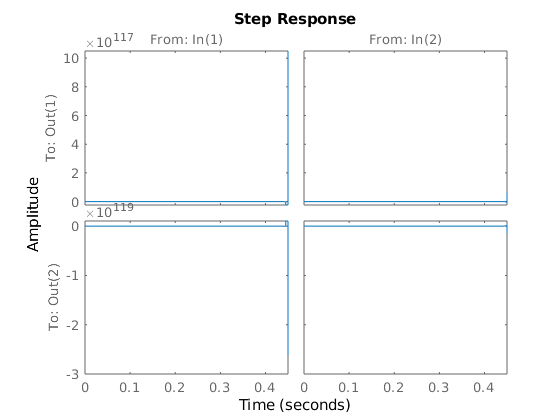

CL = feedback(P1*K1,eye(n1));
step(CL)

X = [1;0];%;0;3];
Xd = [0;0];%;0;0];
for i = 1:100    
    X = (A1-B1*K1)*X + B1*K1*Xd;
    u = -K1*X;
    disp(X);
end

         0
 -412.9318

   1.0e+04 *

   -0.0413
    1.4081

   1.0e+05 *

    0.1408
   -3.0968

   1.0e+06 *

   -0.3097
    4.7459

   1.0e+07 *

    0.4746
   -3.3962

   1.0e+08 *

   -0.3396
   -8.0158

   1.0e+10 *

   -0.0802
    4.1359

   1.0e+12 *

    0.0414
   -1.0794

   1.0e+13 *

   -0.1079
    1.9730

   1.0e+14 *

    0.1973
   -2.2710

   1.0e+14 *

   -2.2710
   -4.0260

   1.0e+17 *

   -0.0040
    1.0751

   1.0e+18 *

    0.1075
   -3.4999

   1.0e+19 *

   -0.3500
    7.4957

   1.0e+21 *

    0.0750
   -1.1109

   1.0e+21 *

   -1.1109
    6.9314

   1.0e+23 *

    0.0693
    2.2237

   1.0e+25 *

    0.0222
   -1.0445

   1.0e+26 *

   -0.1045
    2.6437

   1.0e+27 *

    0.2644
   -4.7022

   1.0e+28 *

   -0.4702
    5.1184

   1.0e+29 *

    0.5118
    1.9625

   1.0e+31 *

    0.0196
   -2.7828

   1.0e+32 *

   -0.2783
    8.6793

   1.0e+34 *

    0.0868
   -1.8106

   1.0e+35 *

   -0.1811
    2.5905

   1.0e+36 *

    0.2591
   -1.3573

   1.0e+37 *

 

## MPC formulation

R = 0.1*eye(2);
RD = 0.1*eye(2);  %Weight the slew rate - respect actuation bandwidths
Q = diag([10000,1,1,10,1,1]);
% diag([100,1,1,10,1,1])
% Q = 1;  %Single output
N = 10;  %This is the horizon for MPC

Qbar = [];
Rbar = [];
RbarD = [];
Sx = [];
Su = [];
CAB = [];
for ii = 1:N
    Qbar = blkdiag(Qbar,Q); % nNxnN matrix example if N=10, n= 5 and m = 2 we will get 50 x 50 matrix
    Rbar = blkdiag(Rbar,R); % mNxmN matrix example if N=10, n= 5 and m = 2 we will get 20 x 20 matrix
    RbarD = blkdiag(RbarD,RD); % mNxmN matrix example if N=10, n= 5 and m = 2 we will get 20 x 20 matrix
    Sx = [Sx;C*A^ii];           % nNxn matrix example if N=10, n= 5 and m = 2 we will get 50 x 5 matrix
    if ii==1
        prev_CAB = C*A^(ii-1)*B;
    else
        prev_CAB = prev_CAB + C*A^(ii-1)*B;
    end
    CAB = [prev_CAB CAB];
    Su = [Su;[CAB  zeros(n,m*N -ii*m)]];
end
Su1=  Su(:,1:2);
LL = tril(repmat(eye(2),N));
H = 2*(LL'*Rbar*LL+RbarD+Su'*Qbar*Su);
Lt_Rbart = LL'*Rbar';
b_diag = [];
for ii=0:N-1
    b_diag = [b_diag Lt_Rbart((m*ii+1):(m*ii+m),(m*ii+1):(m*ii+m))];
end
        
Fu = 2*(b_diag+Su1'*Qbar*Su)';  %Note the trick on Rbar - u(-1) is really a scalar
Fr = -2*(Qbar*Su)';
Fx = 2*(Sx'*Qbar*Su)';

Now I have to think a bit more about these constraints for the tracking case.  I'm not constraining the slew rate, so my constraint really comes down to $|u(0)+\Delta u(k)|<1$.  The $W$ matrix will be updated at each step.

G = [tril(repmat(eye(2),N));-tril(repmat(eye(2),N))];
W0 = ones(2*m*N,1)*12;
S = zeros(2*m*N,n);

The pre-computation is done.  Now let's look at an online solution using Matlab's **quadprog** command to solve the optimization problem.

Setup the initial condition and run the approach for T steps (in this case, T seconds).  For sanity's sake, I'll also turn off the reporting that quadprog typically does.

X = [1;0;0;0;0;0];
T = 40;
% r = square([1:T+N+1]/6);
% r = [0;0;2;1;0;0;0;2;1;0;0;0;2;1;0];
r = zeros(1,n*N);
% Z = zeros(2,1);
Z = zeros(m*N,1);
U = [0;0];
options = optimoptions('quadprog');
options.Display = 'none';
X_alpha = [];
X_alphadot = [];
X_vel = [];
X_theta = [];
X_thetadot = [];
U1 = [];
U2 = [];
for ii = 1:T-1
    X_alpha= [X_alpha;X(1)]; %For graphing
    X_alphadot = [X_alphadot;X(2)];
    X_vel = [X_vel;X(4)];
    X_theta = [X_theta;X(5)];
    X_thetadot = [X_thetadot;X(6)];
    f = Fx*X+Fu*U+Fr*r'; %(ii:ii+N-1)';  %Sometimes people hold r(ii) here
    W = W0+[repmat(eye(2),N,1)*-U;repmat(eye(2),N,1)*U];

Solve the QP.

    [Z,~,exitflag,~]= quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
    U = U + Z(1:m);  %Just use the first item   
    U1 = [U1;U(1)];
    U2 = [U2;U(2)];

Now I'll apply the optimal control to the system.

    X = A*X+B*U;
    G*Z - W+S*X;
    exitflag
end

exitflag = 0

exitflag = 0

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 0

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 1

exitflag = 0

% Xact =[Xact;X];

Now let's see how well that worked.

a = 39

a = 39

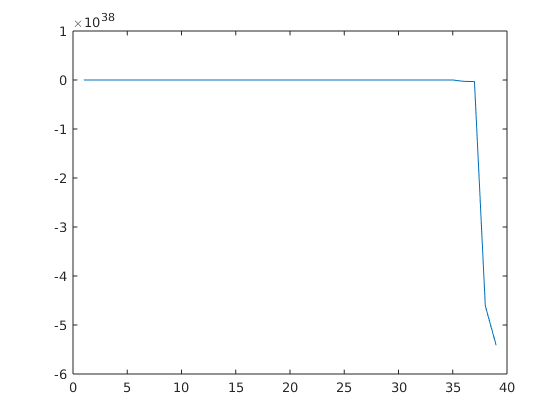

plot(X_alpha(1:a))

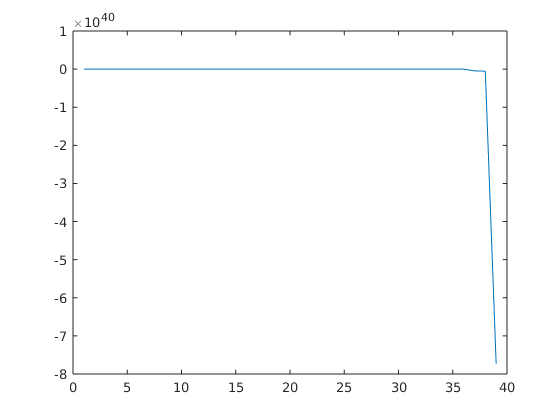

plot(X_alphadot(1:a))

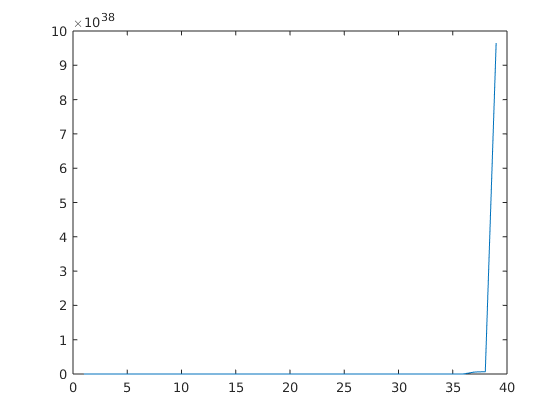

plot(X_vel(1:a))

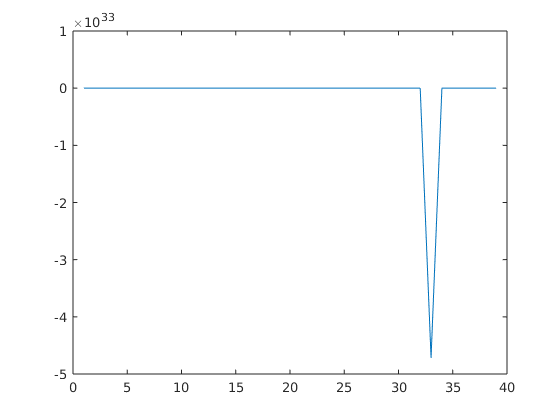

plot(X_theta(1:a))

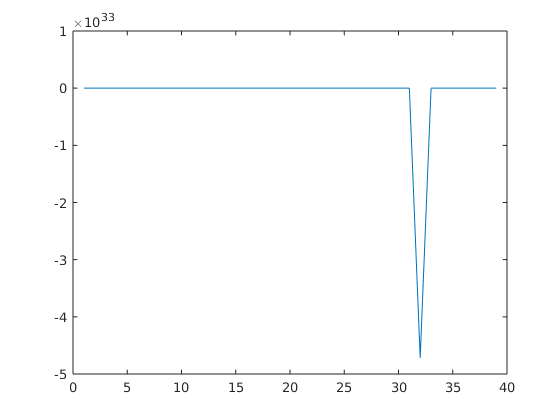

plot(X_thetadot(1:a))

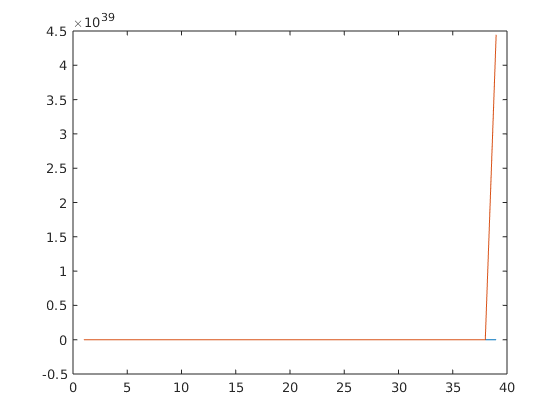

plot(U1(1:a))
hold on
plot(U2(1:a))
hold off